# Mapeo de Codenadas para un robot movil.

## Jhonatan Yael Martinez Vargas - A01734193

Dado la siguiente configuración para un robot movil:

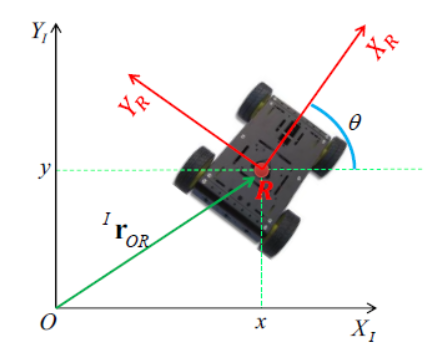

se realiza un codigo que explica como es posible mapear las coordenadas de este robot dada cierta configuración inicial.

% Inicio limpio de MATLAB
clear all
close all
clc

Para poder hacer un mapeo con valores numericos lo que se debe de hacer es lo sigueinte:

## Paso 01 - Definir el $\zeta$ inercial y la matriz de rotacion en "Z".

% --- Ejemplo ---

% Definiendo cordenadas iniciales y theta inicial
x = 1;
y = 1;
th = 45;

% Creacion del vector de posición
xi_inicial = [x; y; th]

xi_inicial =      1
     1
    45


% Creación de la matriz de rotación en "z"
Rotz = [cos(th) -sin(th) 0;
        sin(th)  cos(th) 0;
           0        0    1]

Rotz =     0.5253   -0.8509         0
    0.8509    0.5253         0
         0         0    1.0000


## Paso 02 - Transformar $\zeta$ inercial a $\zeta$ local.

% Transformación de marcos
xi_local = Rotz * xi_inicial

xi_local =    -0.3256
    1.3762
   45.0000


## Paso 03 - Magnitud de $\zeta$ local.

% Magnitud de xi_local
mgn = sqrt(xi_local(1) ^ 2 + xi_local(2) ^ 2) 

mgn = 1.4142

## Paso 04 - Transformar $\zeta$ local a $\zeta$ inercial.

% Inv(Rotz) * xi_local =  Rotz '\' xi_local
xi_inercial = Rotz \ xi_local

xi_inercial =      1
     1
    45


## Ejercicios:

## a) **(-5, 9, 2°)**

x1 = -5;
y1 = 9;
th1 = -2;

Pos_1 = [x1; y1; th1]

Pos_1 =     -5
     9
    -2



Rotz1 = [cos(th1) -sin(th1) 0;
        sin(th1)  cos(th1) 0;
           0        0    1]

Rotz1 =    -0.4161    0.9093         0
   -0.9093   -0.4161         0
         0         0    1.0000


xi_local_1 = Rotz1 * Pos_1

xi_local_1 =    10.2644
    0.8012
   -2.0000


magnitud1 = sqrt(xi_local_1(1) ^ 2 + xi_local_1(2) ^ 2)

magnitud1 = 10.2956

xi_inercial1 = Rotz1 \  xi_local_1

xi_inercial1 =     -5
     9
    -2


## b) **(-3, 8, 63°)**

x2 = -3;
y2 = 8;
th2 = 63;

Pos_2 = [x2; y2; th2];

Rotz2 = [cos(th2) -sin(th2) 0;
        sin(th2)  cos(th2) 0;
           0        0    1]

Rotz2 =     0.9859   -0.1674         0
    0.1674    0.9859         0
         0         0    1.0000


 
xi_local_2 = Rotz2 * Pos_2

xi_local_2 =    -4.2965
    7.3851
   63.0000


magnitud2 = sqrt(xi_local_2(1) ^ 2 + xi_local_2(2) ^ 2)

magnitud2 = 8.5440

xi_inercial2 = Rotz2 \  xi_local_2

xi_inercial2 =    -3.0000
    8.0000
   63.0000


## c) **(5, -2, 90°)**

x3 = 5;
y3 = -2;
th3= 90;

Pos_3 = [x3; y3; th3];

Rotz3 = [cos(th3) -sin(th3) 0;
        sin(th3)  cos(th3) 0;
           0        0    3]

Rotz3 =    -0.4481   -0.8940         0
    0.8940   -0.4481         0
         0         0    3.0000


 
xi_local_3 = Rotz3 * Pos_1

xi_local_3 =    -5.8056
   -8.5026
   -6.0000


magnitud3 = sqrt(xi_local_3(1) ^ 2 + xi_local_3(2) ^ 2)

magnitud3 = 10.2956

xi_inercial3 = Rotz3 \ xi_local_3

xi_inercial3 =    -5.0000
    9.0000
   -2.0000


## d) **(0, 0, 180°)**

x4 = 0;
y4 = 0;
th4 = 180;

Pos_4 = [x4; y4; th4];
 
Rotz4 = [cos(th4) -sin(th4) 0;
        sin(th4)  cos(th4) 0;
           0        0    1]

Rotz4 =    -0.5985    0.8012         0
   -0.8012   -0.5985         0
         0         0    1.0000



xi_local_4 = Rotz4 * Pos_4

xi_local_4 =      0
     0
   180


magnitud4 = sqrt(xi_local_4(1) ^ 2 + xi_local_4(2) ^ 2)

magnitud4 = 0

xi_inercial4 = Rotz4 \ xi_local_4

xi_inercial4 =      0
     0
   180


## e) **(-6, 3, -55°)**

x5 = -6;
y5 = 3;
th5 = -55;

Pos_5 = [x5; y5; th5];
 
Rotz5 = [cos(th5) -sin(th5) 0;
        sin(th5)  cos(th5) 0;
           0        0    1]

Rotz5 =     0.0221   -0.9998         0
    0.9998    0.0221         0
         0         0    1.0000



xi_local_5 = Rotz5 * Pos_5

xi_local_5 =    -3.1320
   -5.9322
  -55.0000



magnitud5 = sqrt(xi_local_5(1) ^ 2 + xi_local_5(2) ^ 2)

magnitud5 = 6.7082

xi_inercial5 = Rotz5 \ xi_local_5

xi_inercial5 =     -6
     3
   -55
